# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** :서원형**

**학번**** :201716201**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/won-hyeong-seo/DSP.git**

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

n = -200:0.25:200;
x5n = 5*(cos(0.49 * pi * n) + cos(0.51 * pi * n))

x5n =    10.0000    9.2385    7.0702    3.8258   -0.0000   -3.8239   -7.0632   -9.2248   -9.9803   -9.2157   -7.0493   -3.8126    0.0000    3.8069    7.0284    9.1748    9.9211    9.1566    7.0005    3.7843    0.0000   -3.7749   -6.9658   -9.0885   -9.8229   -9.0613   -6.9242   -3.7411    0.0000    3.7280    6.8757    8.9663    9.6858    8.9302    6.8205    3.6832   -0.0000   -3.6664   -6.7585   -8.8088   -9.5106   -8.7639   -6.6898   -3.6107   -0.0000    3.5903    6.6146    8.6165    9.2978    8.5630


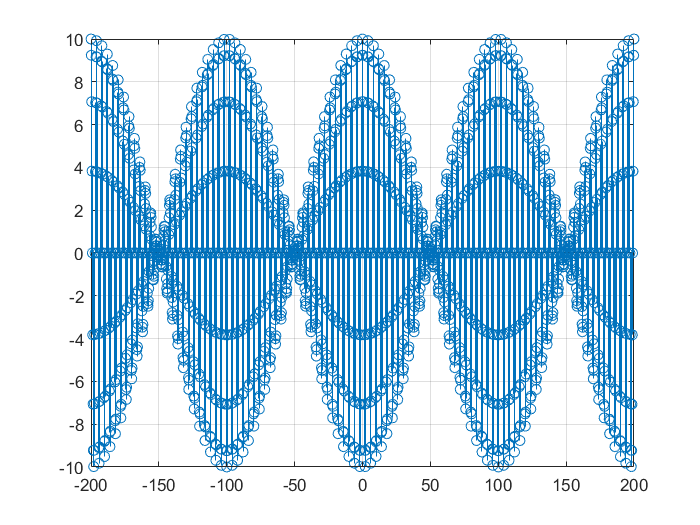


figure(1)
stem(n,x5n)
grid on

2) 

n = 0 : 100;
x7n = exp(-0.05 * n) .* sin(0.1 * pi * n + pi / 3)

x7n =     0.8660    0.9304    0.8999    0.7863    0.6084    0.3894    0.1540   -0.0737   -0.2726   -0.4267   -0.5253   -0.5643   -0.5458   -0.4769   -0.3690   -0.2362   -0.0934    0.0447    0.1654    0.2588    0.3186    0.3423    0.3310    0.2893    0.2238    0.1433    0.0567   -0.0271   -0.1003   -0.1570   -0.1932   -0.2076   -0.2008   -0.1754   -0.1358   -0.0869   -0.0344    0.0164    0.0608    0.0952    0.1172    0.1259    0.1218    0.1064    0.0823    0.0527    0.0208   -0.0100   -0.0369   -0.0577


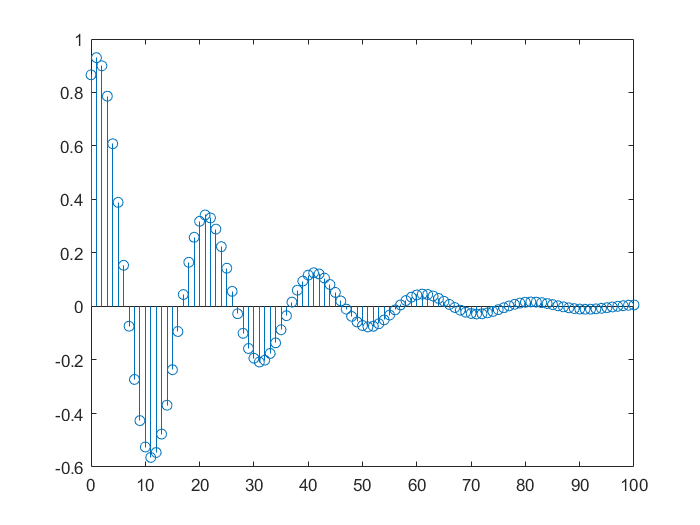

figure(2)
stem(n, x7n)

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

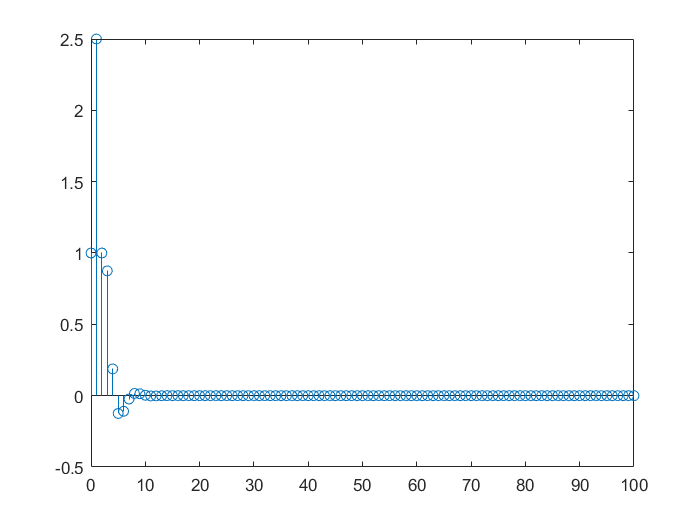

b = [1 2 0 1];
a = [1 -0.5 0.25];
n = 0:100;

h = impz(b,a,n);

figure(3)
stem(n,h)

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 5.8571

3) 만약 이 시스템의 입력이 x(n) = [5 + 3cos(0.2*pi*n) + 4sin(0.6*pi*n)]u(n)  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

n = 0 : 200;
x23n = 5 + 3 * cos(0.2 * pi * n) + 4 * sin(0.6 * pi * n)

x23n =     8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228    8.0000   11.2313    3.5759    1.7218    6.3772    2.0000   -1.2313    6.4241    8.2782    3.6228


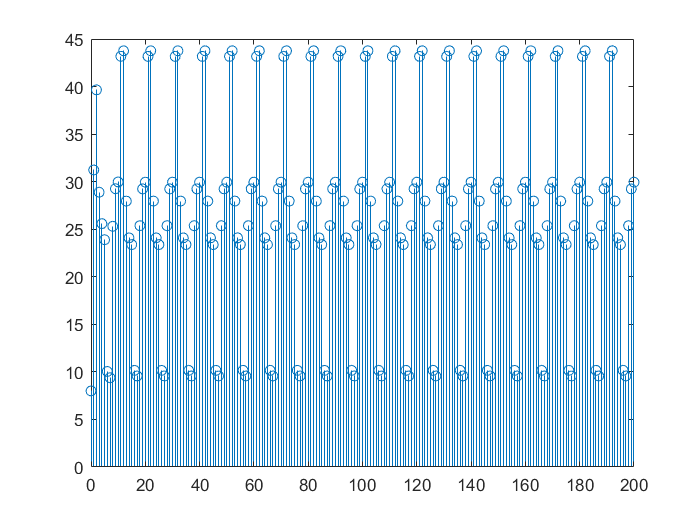

y23n = filter(b, a, x23n);
figure(4)
stem(n, y23n)

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

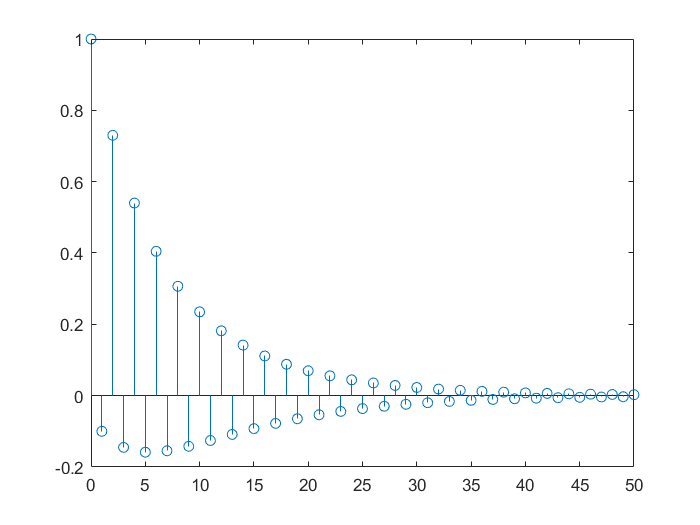

n31 = 0 : 50;
k31 = 0 : n31;
x31n = 0.8 .^ n31;
h31n = (-0.9) .^ n31;
y31n = (-0.9).^n31 .* (1 - (-8/9).^(n31+1)) * 9/17;

figure(5)
stem(n31, y31n)

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

nn = 1 : 26;
x32n = x31n(nn)

x32n =     1.0000    0.8000    0.6400    0.5120    0.4096    0.3277    0.2621    0.2097    0.1678    0.1342    0.1074    0.0859    0.0687    0.0550    0.0440    0.0352    0.0281    0.0225    0.0180    0.0144    0.0115    0.0092    0.0074    0.0059    0.0047    0.0038


h32n = h31n(nn)

h32n =     1.0000   -0.9000    0.8100   -0.7290    0.6561   -0.5905    0.5314   -0.4783    0.4305   -0.3874    0.3487   -0.3138    0.2824   -0.2542    0.2288   -0.2059    0.1853   -0.1668    0.1501   -0.1351    0.1216   -0.1094    0.0985   -0.0886    0.0798   -0.0718


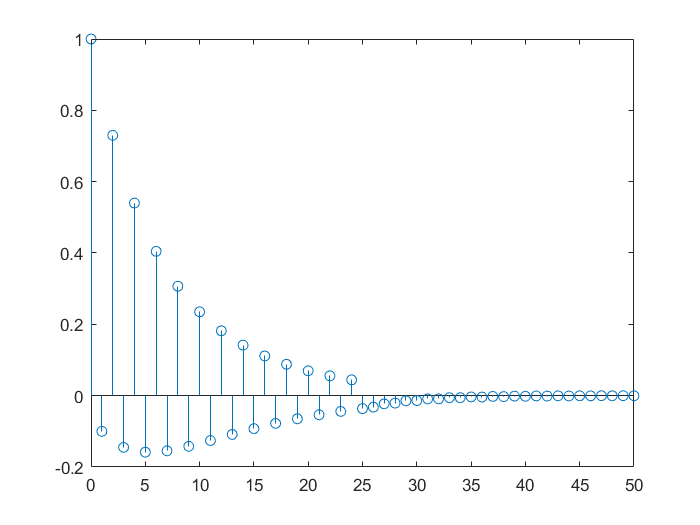

n32 = 0 : 50;

y32n = conv(x32n, h32n);
figure(6)
stem(n32, y32n)

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

a33 = [1 0.9];
b33 = 1;
y33n = filter(b33, a33, x31n)

y33n =     1.0000   -0.1000    0.7300   -0.1450    0.5401   -0.1584    0.4047   -0.1545    0.3068   -0.1419    0.2351   -0.1257    0.1819   -0.1087    0.1418   -0.0924    0.1113   -0.0777    0.0879   -0.0647    0.0698   -0.0536    0.0556   -0.0441    0.0445   -0.0362    0.0356   -0.0296    0.0286   -0.0242    0.0230   -0.0197    0.0186   -0.0161    0.0150   -0.0131    0.0121   -0.0106    0.0098   -0.0086    0.0079   -0.0070    0.0064   -0.0057    0.0052   -0.0046    0.0042   -0.0037    0.0034   -0.0030



stem(n31, y33n);

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

w41 = [-1000 : 1000] * pi / 1000;
H41w = exp(j*w41)./(exp(j*w41) - 0.9*ones(1,2001)) + exp(-j*w41)./(exp(-j*w41)-0.9*ones(1,2001))-ones(1,2001)

H41w =     0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0526    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0527    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0528    0.0529    0.0529    0.0529    0.0529    0.0529    0.0529    0.0529    0.0529


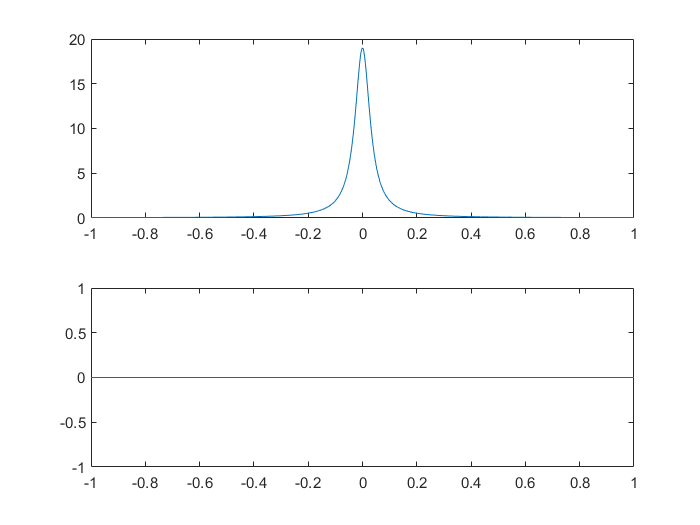

magH41 = abs(H41w); angH41 = angle(H41w);
figure(10)
subplot(2,1,1)
plot(w41/pi , magH41)
subplot(2,1,2)
plot(w41/pi, angH41/pi)

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

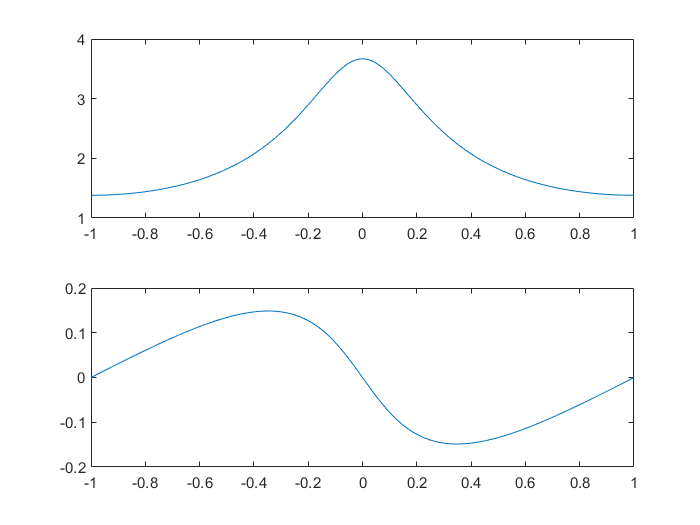

w42 = [-1000 : 1000] * pi / 1000;
H42w = exp(j*w42) ./ (exp(j*w42) - 0.5 * ones(1,2001)) + exp(j*w42) ./ (exp(j*w42) - 0.4 * ones(1,2001));
magH42 = abs(H42w); angH42 = angle(H42w);
figure(11)
subplot(2,1,1)
plot(w42/pi , magH42)
subplot(2,1,2)
plot(w42/pi, angH42/pi)

5. (P3.17) 

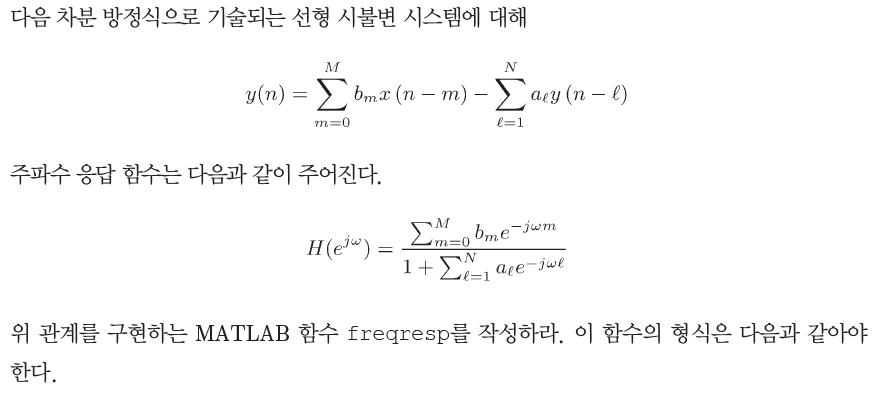

%함수가 가운데 있으면 뒤에 있는 것들이 실행이 안돼서 주석처리 했습니다.

% function [H] = freqresp(b,a,w)
% % H = frequency response array evaluated at w frequencies
% % b = numerator coefficient array
% % a = denominator coefficient array (a(1) = 1)
% % w = frequency location array

% m = 0 : length(b)-1;
% l = 0 : length(a)-1;
% qnswk = b * exp(-j * m' * w);
% qnsah = a * exp(-j * l' * w);
% H = qnswk ./ qnsah;

% end

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

a61 = [1.0000, -0.9500, 0.9025];
b61 = [1.0000 0.0000 -1]

b61 =      1     0    -1


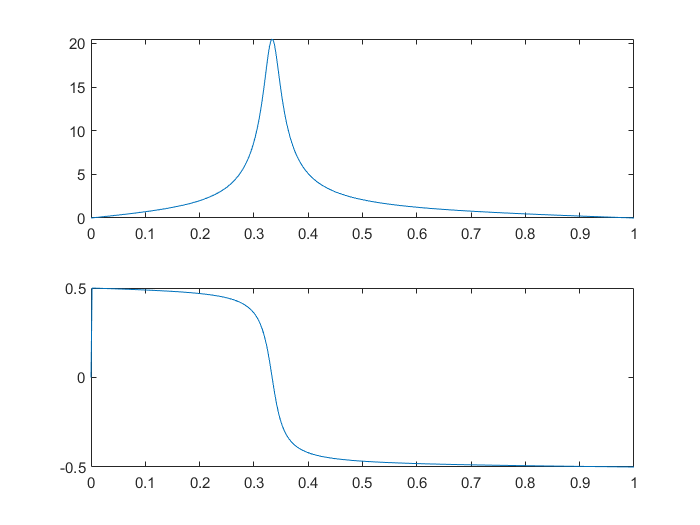

K = 500; k = 0 : K;
w61 = pi * k / K;

m61 = 0 : length(b61)-1;
l61 = 0 : length(a61)-1;

qnswk61 = b61 * exp(-j * m61' * w61);
qnsah61 = a61 * exp(-j * l61' * w61);

H61 = qnswk61 ./ qnsah61;

magH61 = abs(H61); angH61 = angle(H61);
figure(8)
subplot(2,1,1)
plot(w61/pi, magH61)

subplot(2,1,2)
plot(w61/pi, angH61/pi)

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

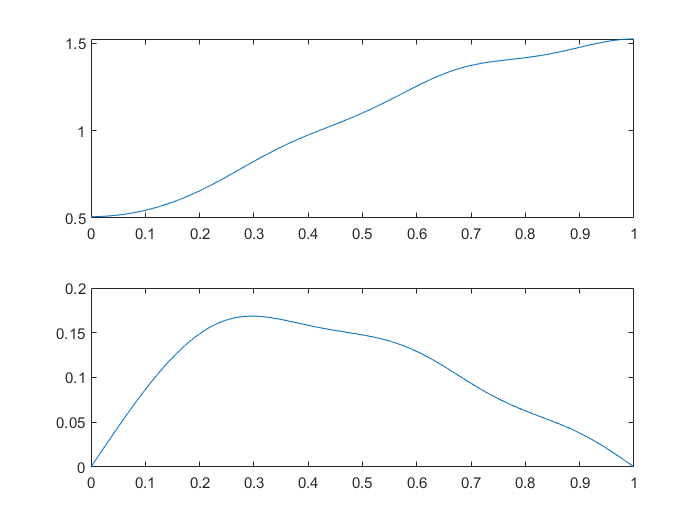

a62 = [1.0000 0.5000 0.2500 0.1250 0.0625 0.03125];
b62 = 1;

K = 500; k = 0 : K;
w61 = pi * k / K;

m62 = 0 : length(b62)-1;
l62 = 0 : length(a62)-1;

qnswk62 = b62 * exp(-j * m62' * w61);
qnsah62 = a62 * exp(-j * l62' * w61);

H62 = qnswk62 ./ qnsah62;

magH62 = abs(H62); angH62 = angle(H62);
figure(9)
subplot(2,1,1)
plot(w61/pi, magH62)

subplot(2,1,2)
plot(w61/pi, angH62/pi)